## **Driver test program to check Clothoids library**

**Test G2 clothoid**

close all;

% G2 fitting data
x0     = -1;
y0     = 0;
theta0 = pi*0.9;
kappa0 = 0.2 + 1e-10;

x1     = 1;
y1     = 0;
theta1 = -pi*1.001;
kappa1 = 0.2 + 0;

figure('Position',[1,1,800,500]);
subplot(2,2,[1,3]);

% compute G2 clothoid

S = ClothoidList();
iter = S.build_3arcG2(x0,y0,theta0,kappa0,x1,y1,theta1,kappa1);
iter

iter = int64
   3


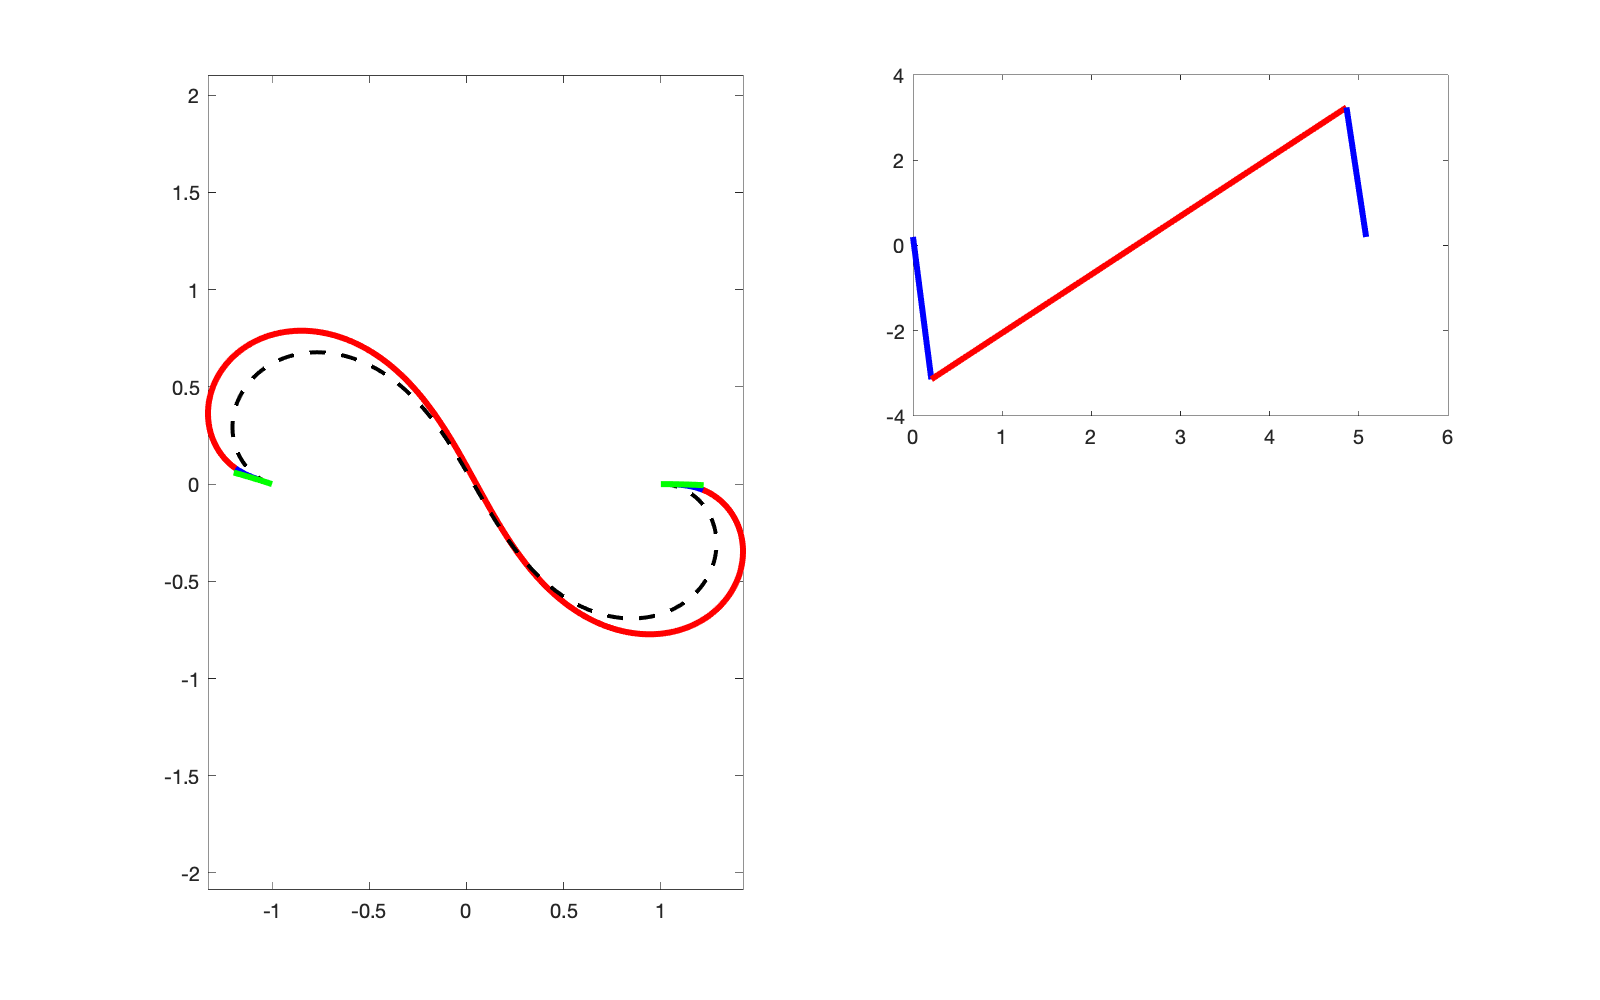

if iter > 0 
  S.plot();
end
axis equal;

SG = ClothoidCurve();
SG.build_G1(x0,y0,theta0,x1,y1,theta1);
SG.plot(1000,'--k','Linewidth',2);
hold on

S0 = S.get(1);
S1 = S.get(3);
C0 = CircleArc( x0, y0, theta0, kappa0, S0.length() );
C1 = CircleArc( x1, y1, theta1, kappa1, -S1.length() );

C0.plot(100,{'Color','green','Linewidth',3});
C1.plot(100,{'Color','green','Linewidth',3});

subplot(2,2,2);
S.plotCurvature(1000);

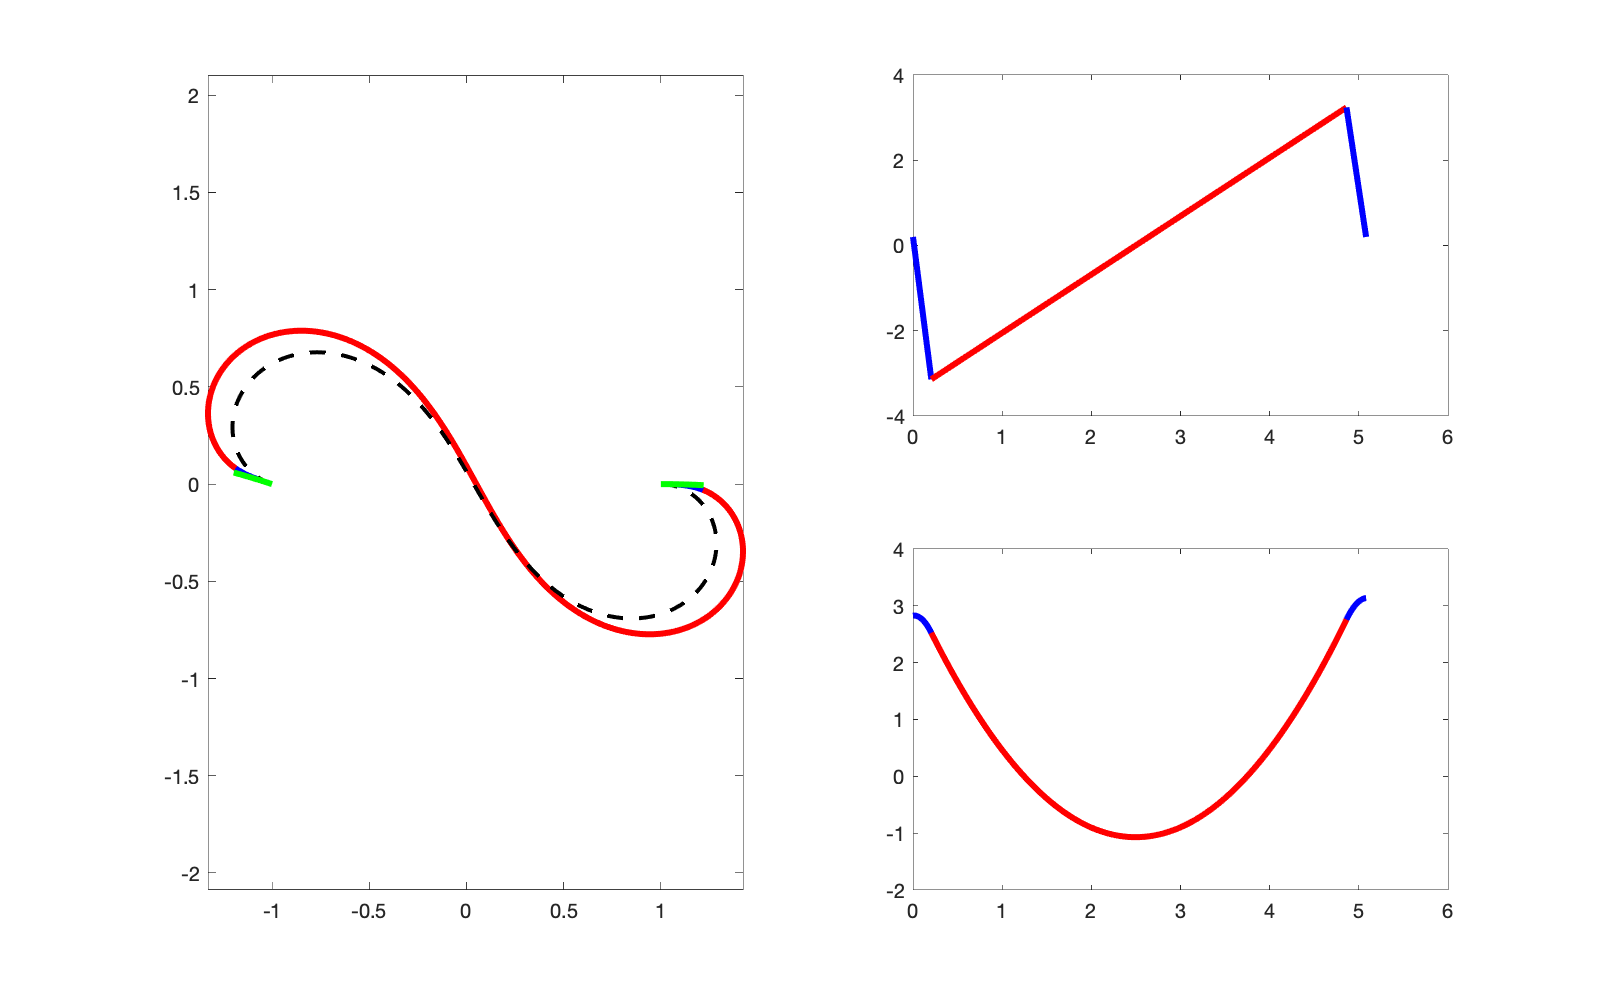

subplot(2,2,4);
S.plotAngle(1000);